# Fenchel Young Divergence Neural Network: a synthetic simulation

We consider a feedforward neural network with $L=2$ layers.

                                                                        
$$$$x_1=\tanh(W_1 x)$$
$$x_2=\tanh(W_2 x_1)$$
$$x_3=W_3 x_2$$$$
 

where $$x \in \mathbb{R}^n$$ is the input, $\hat{y}:=x_3 \in \mathbb{R}^3$ is the output and $$W_1 \in \mathbb{R}^{n_1 \times n}, W_2 \in \mathbb{R}^{n_2 \times n_1}, W_3 \in \mathbb{R}^{p \times n_2}$$. We consider a synthetic model, for which a true model with $$W_1^{\text{true}}, W_2^{\text{true}}, W_3^{\text{true}}$$ exists. We then produce random test and training inputs, and observe the outputs produced by the neural network. We then try to learn $$W_1, W_2, W_3$$ from this synthetic data. Note that this is a regression problem. As a loss function we will use the mean squared error. We compare two methods:

- classic RMSprop algorithm (backpropagation)

- our own method that builds on Fenchel-Young Divergence Neural Nets and Block Coordinate Descent (BCD)

clear all;
% we declare the global variables used in this live editor
global true_weights weights hidden_var data sizes hparam objective RMSE tests
true_weights = struct;
weights = struct;
hidden_var = struct;
hparam = struct;
objective = struct;
RMSE = struct;
tests = struct;
global K iter
global count_figure
count_figure = 0;

## Load the synthetic training model

load('sizes.mat'); load('data.mat'); load('true_weights');

## Training the Neural Network using RMSprop

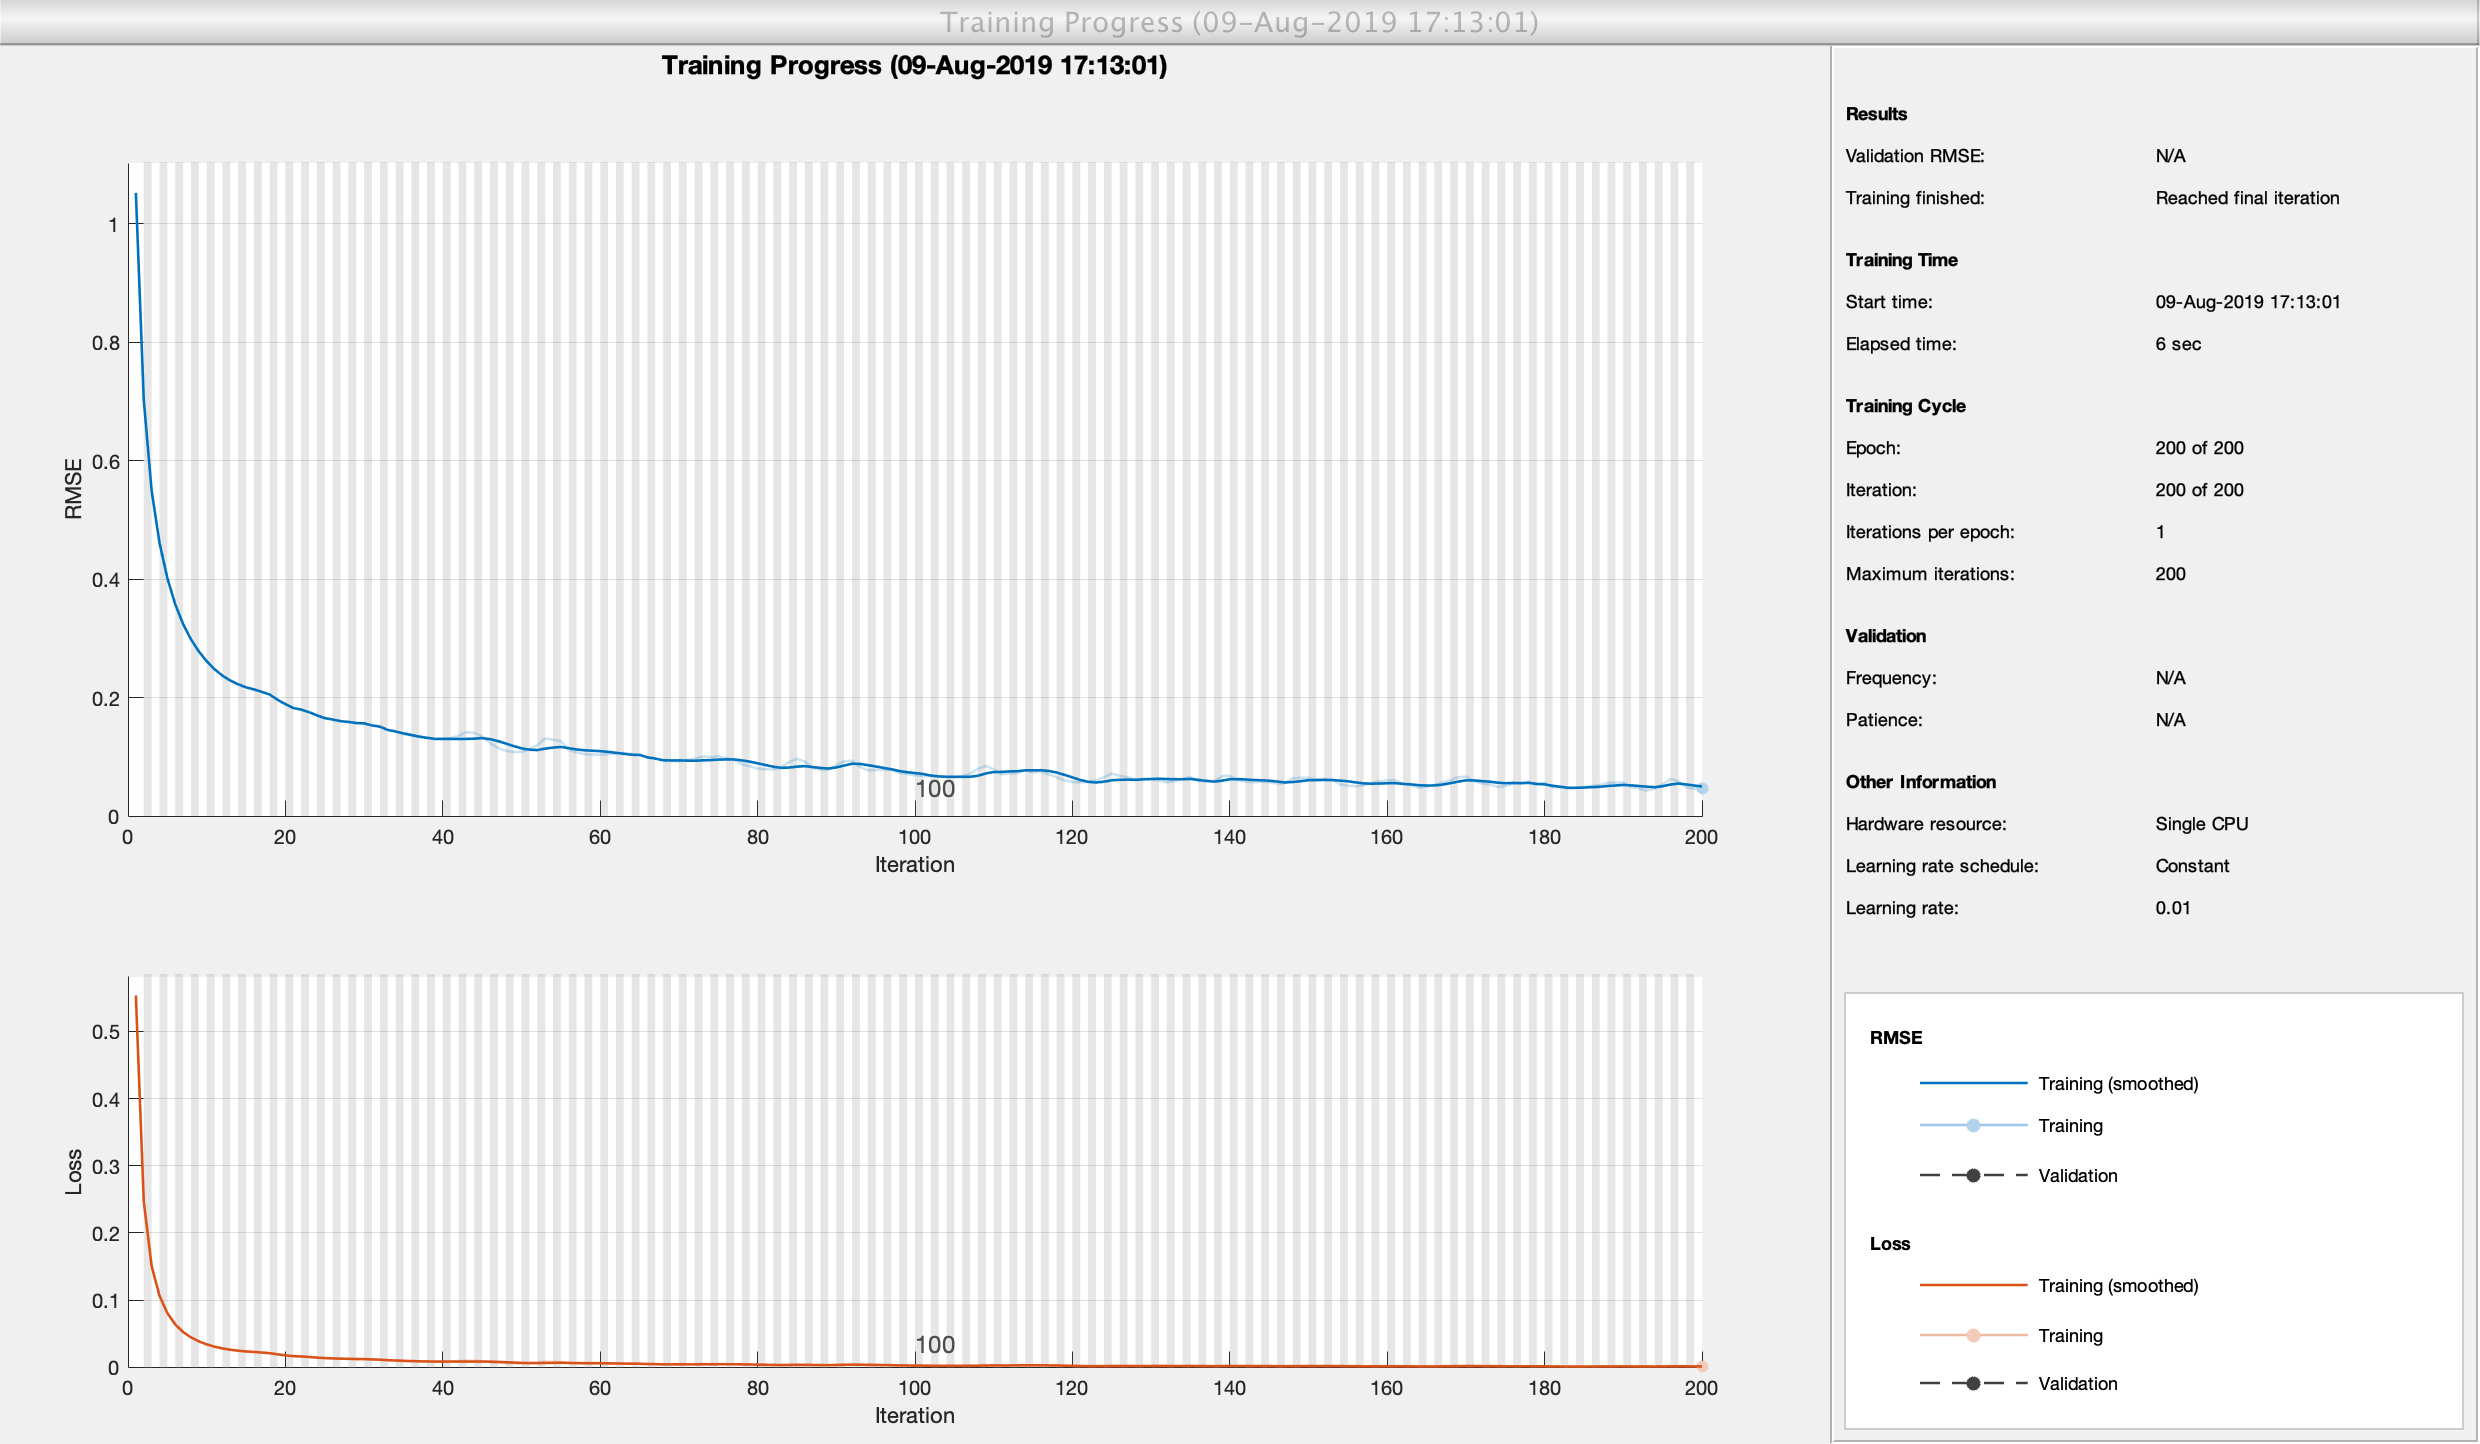

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         1.05 |          0.6 |          0.0100 |
|       2 |           2 |       00:00:01 |         0.70 |          0.2 |          0.0100 |
|       3 |           3 |       00:00:01 |         0.55 |          0.2 |          0.0100 |
|       4 |           4 |       00:00:01 |         0.46 |          0.1 |          0.0100 |
|       5 |           5 |       00:00:01 |         0.40 |      8.1e-02 |          0.0100 |
|       6 |           6 |       00:00:01 |         0.36 |      6.4e-02 |          0.0100 |
|       7 |           7 |       00:00:01 |         0.32 |      5.3

layers = [
    sequenceInputLayer(sizes.n)
    fullyConnectedLayer(sizes.n_1)
    tanhLayer 
    fullyConnectedLayer(sizes.n_2)
    tanhLayer 
    fullyConnectedLayer(sizes.p)
    regressionLayer];

options = trainingOptions('rmsprop','MaxEpochs',200,'MiniBatchSize',sizes.m_train,'InitialLearnRate',0.01,'VerboseFrequency',1,'Plots',"training-progress");
    
net = trainNetwork(data.X_train, data.Y_train, layers, options);

% Sanity Check 
weights.W_1_nn= net.Layers(2, 1).Weights;
weights.bias_1_nn = net.Layers(2, 1).Bias;
weights.W_2_nn = net.Layers(4, 1).Weights;
weights.bias_2_nn = net.Layers(4, 1).Bias;
weights.W_3_nn = net.Layers(6, 1).Weights;
weights.bias_3_nn = net.Layers(6, 1).Bias;
[training_error,test_error]=error_model_nn();
disp('RMSE (test set): '); disp(training_error);

RMSE (test set): 
    0.0506



disp('RMSE (train set): '); disp(test_error);

RMSE (train set): 
    0.0524



## Training Neural Network using BCD on Fenchel-Young Divergence Neural Net

The corresponding Fenchel Multiconvex formulation with decaying feedback weight $\mu$ reads

                                      
$$$$\min \frac{1}{2}\|Y-W_3 X_2\|_F^2+\varepsilon \Big\{\Phi^\star (X_2)+\Phi (W_2 X_1)-\langle X_2,W_2 X_1 \rangle \Big\}+ \varepsilon^2 \Big\{\Phi^\star (X_1)+\Phi(W_1 X)-\langle X_1,W_1 X\rangle  \Big\} $$$$


where $$X=[x(1),\cdots, x(m_{train})], \ X_1=[x_1(1),\cdots, x_1 (m_{train})], X_2=[x_2(1),\cdots, x_2 (m_{train})] $$ are the matrix input vector and matrices hidden vectors.

Classic BCD consists in applying recursively the following updates

$$W_3$$** update** 

                                                                                
$$$\min_{W_3} \frac{1}{2}\|Y-W_3 X_2\|_F^2 $$$


This is a linear regression. The closed form solution reads:   $ $$W_3=YX_2^{\top} (X_2 X_2^{\top})^\dagger$$$

With L2 regularization this reads:   $ $$W_3=YX_2^{\top} (X_2 X_2^{\top}+\rho I)^{-1}$$$

$$X_2$$** update **

                                                              
$$$$\min_{X_2}\frac{1}{2}\|Y-W_3 X_2\|_F^2+\varepsilon \Big\{ \Phi^\star (X_2)- \langle X_2,W_2 X_1 \rangle \Big\}$$$$


    Note that implicitely $-1 \leq X_2 \leq 1$.

$$W_2$$** update** 

                                                                          
$$$\min_{W_2}  \Phi (W_2 X_1)-\langle X_2,W_2 X_1 \rangle $$$


The gradient of the objective is:      $\tanh(W_2X_1)X_1^\top-X_2 X_1^\top$

$$X_1$$** update** 

                                                        
$$$\min_{X_1} \varepsilon \{ \Phi (W_2 X_1)- \langle X_2,W_2 X_1 \rangle \} +\varepsilon^2\{\Phi^\star (X_1)-\langle X_1,W_1 X\rangle\}$$$


$$W_1$$** update**, similar to $$W_2$$ update. The gradient is:         $\tanh(W_1X)X^\top-X_1 X^\top$

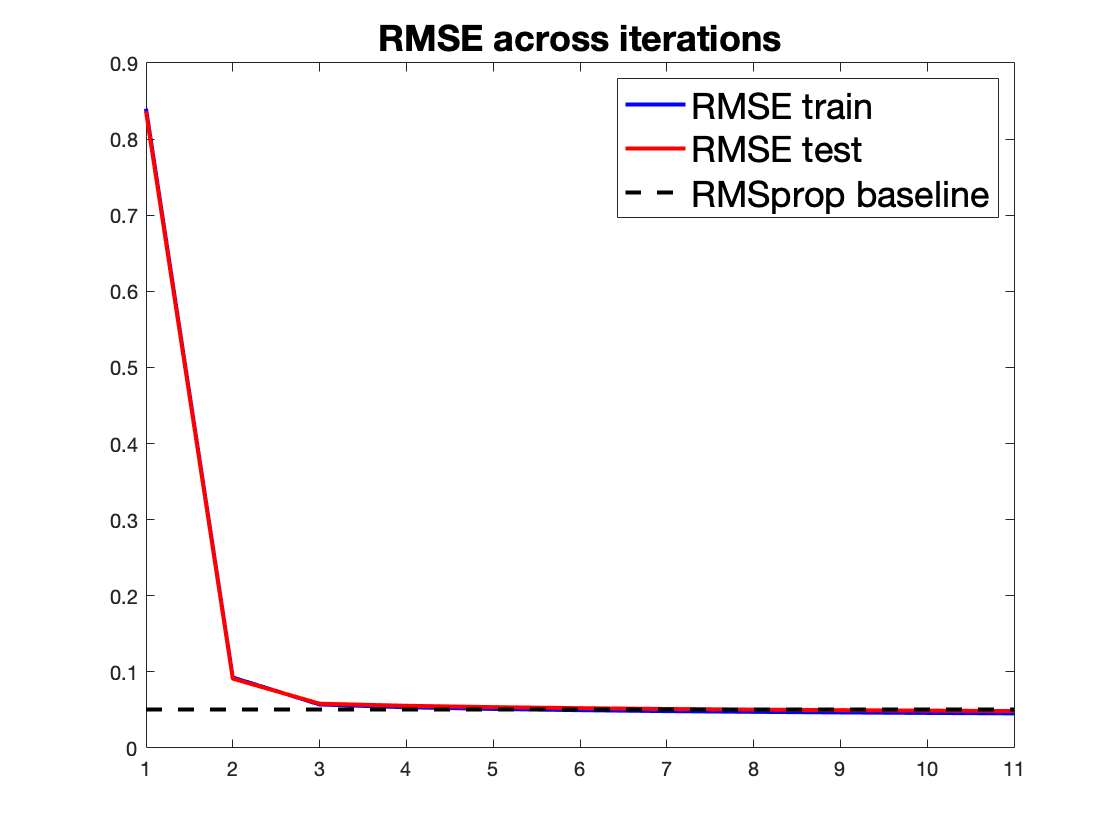

RMSE (test set): 
    0.0486

RMSE (train set): 
    0.0455



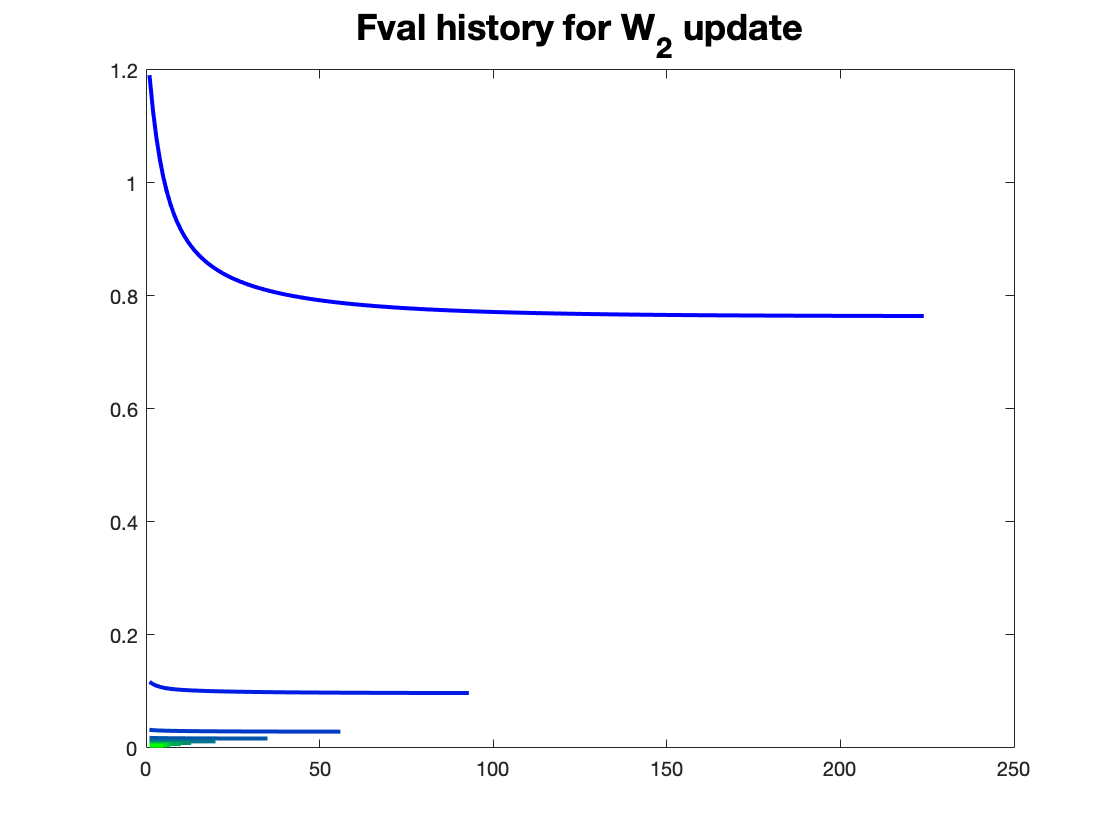

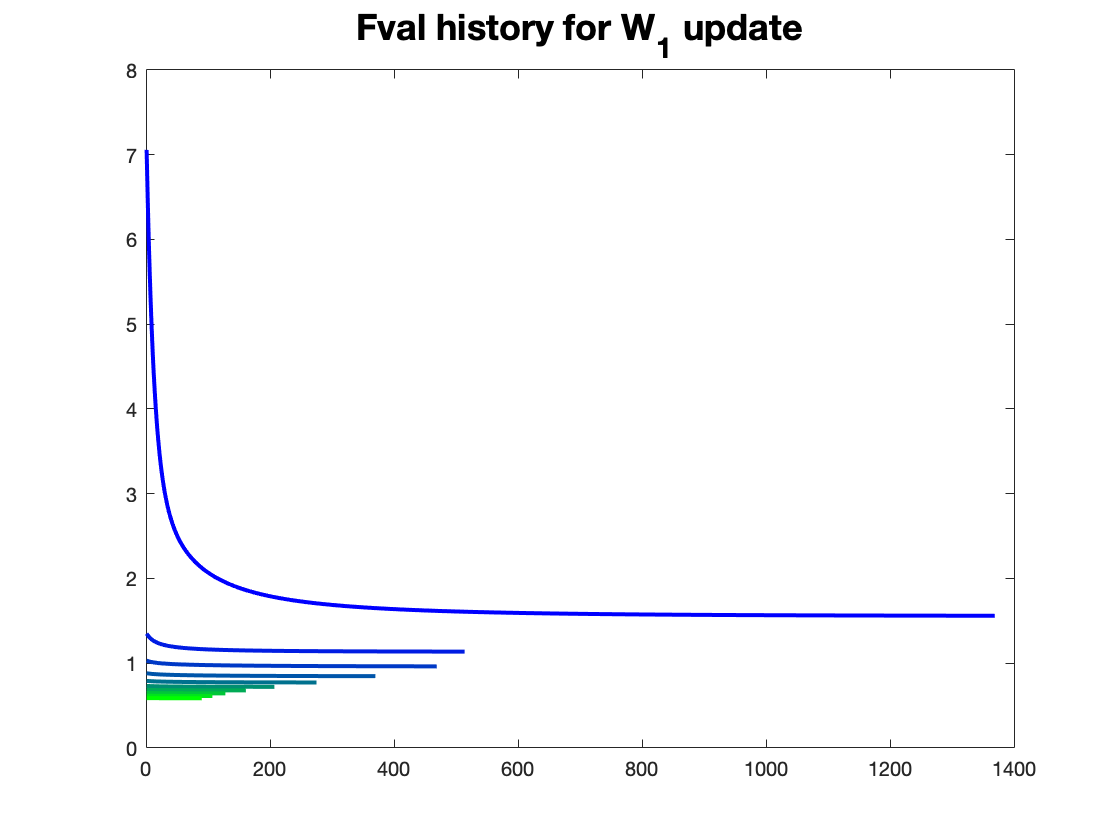

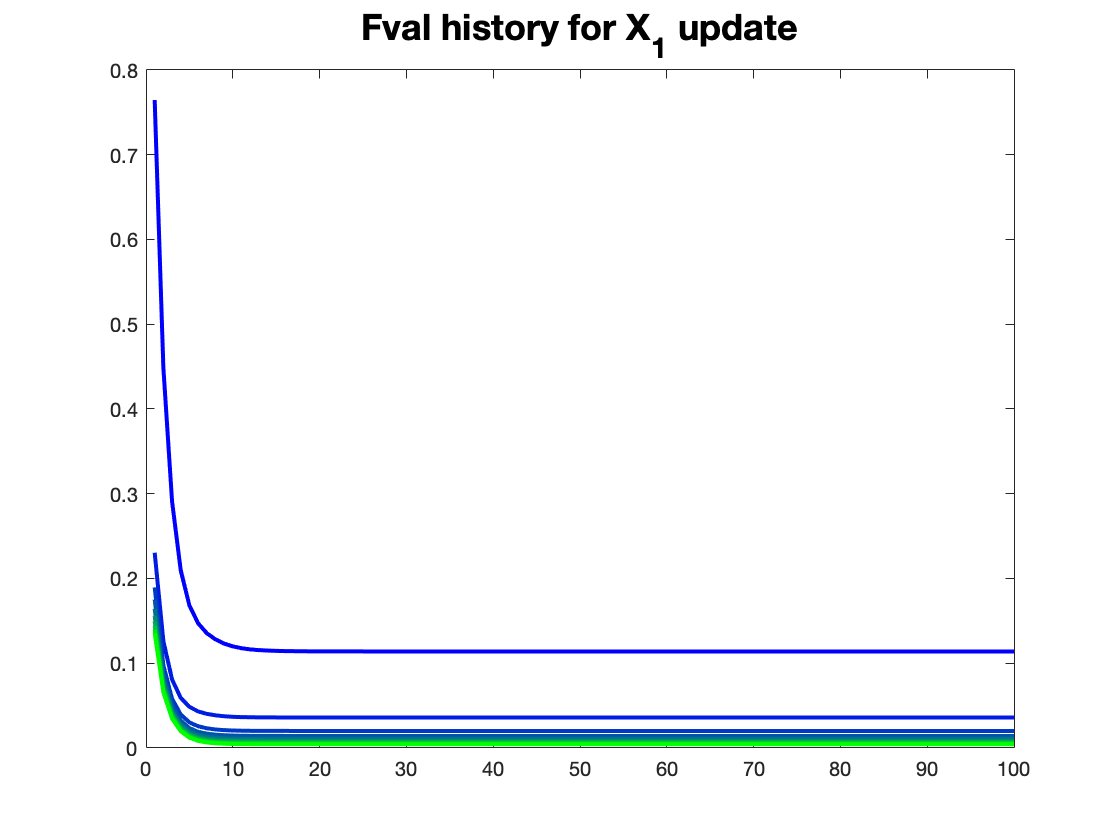

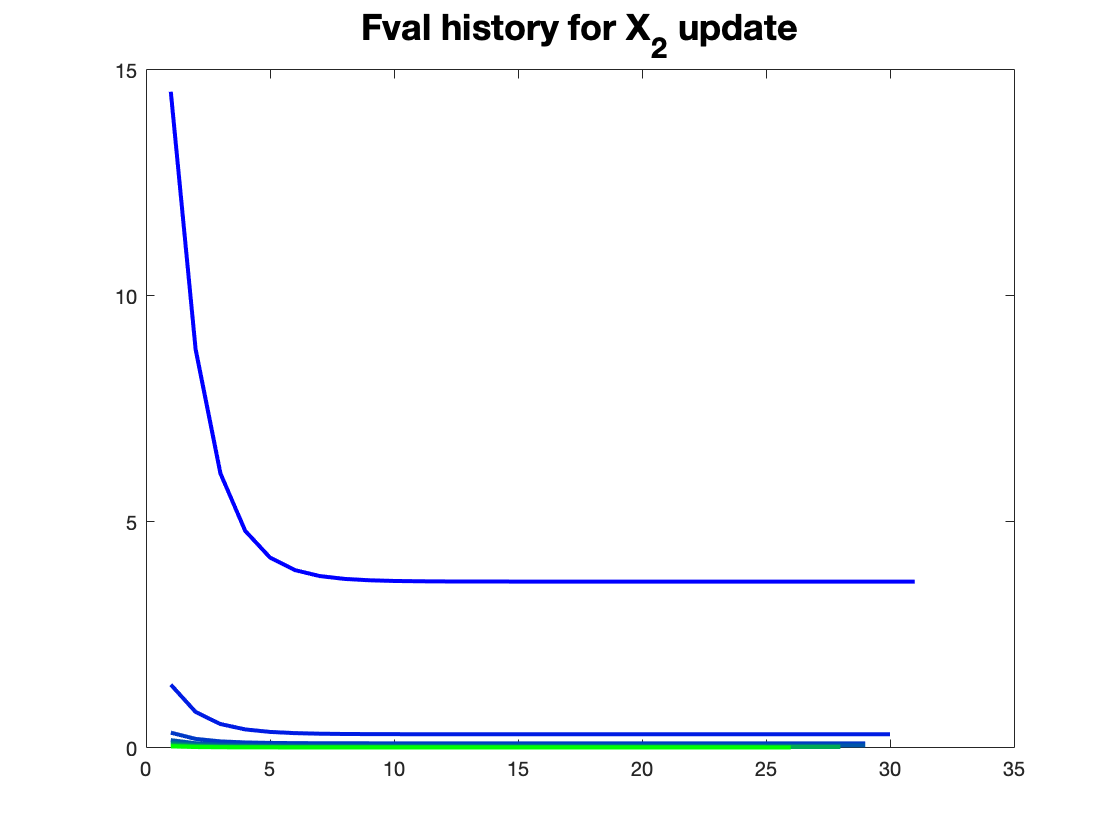

K = 10;
hparam.epsilon = 10^-3;

% Initialize weights and variables
weights.W_1_init = rand(sizes.n_1,sizes.n)-0.5; 
weights.W_2_init = rand(sizes.n_2,sizes.n_1)-0.5;
weights.W_3_init = rand(sizes.p,sizes.n_2)-0.5; 
initialize

% keep RMSE throughout iterations
[RMSE.init_train,RMSE.init_test] = error_model();
[objective.init_fval_fenchel_1, objective.init_fval_fenchel_2] = objective_function();

for iter = 1:K 
    W_3_update('direct');
    X_2_update('newton', 10^-5);
    W_2_update('gradient', 10^-5);
    X_1_update('newton', 10^-5);
    W_1_update('gradient', 10^-5);
    keep_history
end
visualize